## Creating test data to be examined in Spectrograms

The present script is designed to generate synthetic datasets, which, upon analysis via spectrogram, will manifest as a cluster of data points. These resultant spectrograms are to be stored in the form of image files. Subsequently, the dimensions of these clusters will be quantified utilizing another script, titled 'measureSpectrogram.mlx'.

For illustrative purposes, two distinct spectrogram image files shall be produced. The initial instance will depict a big cluster of points within the spectrogram. Conversely, the second instance will showcase a juxtaposition of a sparse cluster and a pronounced chirp signal at a higher frequency range.  

#### Procedure to generate the test data

- Generate normally distributed random numbers

- Apply a band-pass filter to the data such that it become narrow band noise

- Measure the noise level outside of the pass band 

- Create a vector of normally distributed random numbers that has the same level as the noise outside of the pass band.  This is the output data.

- Overwrite the middle few frames of the output data with the narrow band noise data.

### Example 1 --  Generating one big cluster in spectrogram 


fs = 48000; % this is the sampling frequency

% one can design a filter easily using "design filter" live task

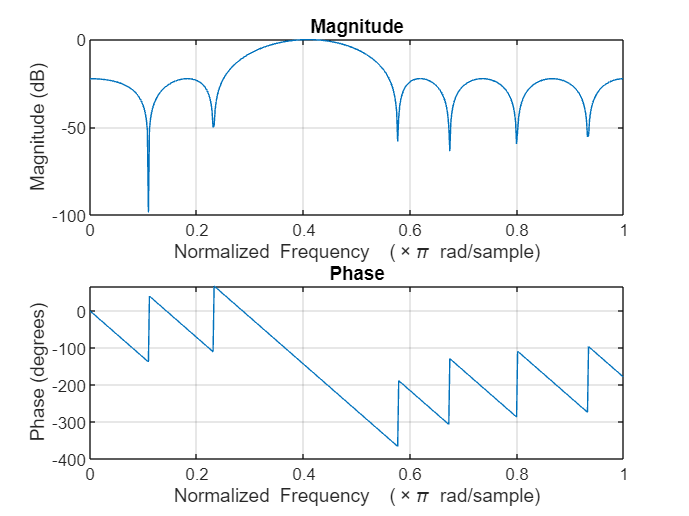

% Design a digital filter
designedFilter2 = designfilt('bandpassfir', ...
    'StopbandFrequency1',0.25,'PassbandFrequency1',0.4, ...
    'PassbandFrequency2',0.41,'StopbandFrequency2',0.65, ...
    'StopbandAttenuation1',20,'PassbandRipple',1, ...
    'StopbandAttenuation2',20);

% Visualize magnitude and phase responses
freqz(designedFilter2.Coefficients)


% designedFilter2 = designfilt('bandpassfir', ...
%     'StopbandFrequency1',0.25,'PassbandFrequency1',0.4, ...
%     'PassbandFrequency2',0.41,'StopbandFrequency2',0.65, ...
%     'StopbandAttenuation1',20,'PassbandRipple',1, ...
%     'StopbandAttenuation2',20);

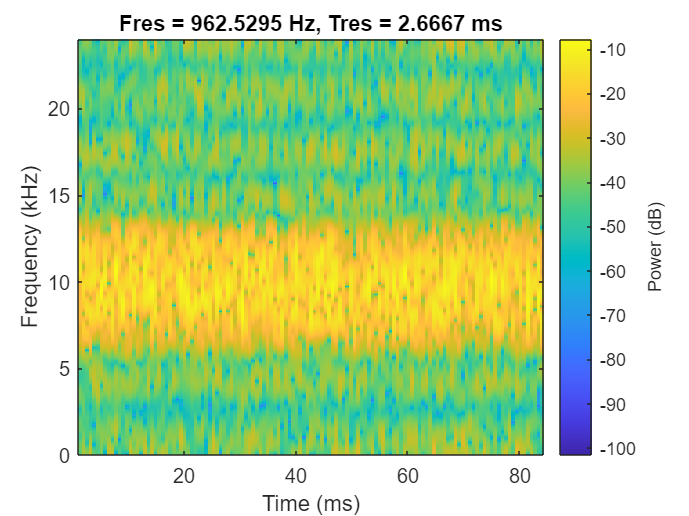

nn = 1024*4;                % the total number of samples
dat = randn(nn,1);          % generated normal distributed random values

% filter the random values to create a narrow band noise
yyn = filter(designedFilter2,dat);
pspectrum(yyn,fs,"spectrogram")

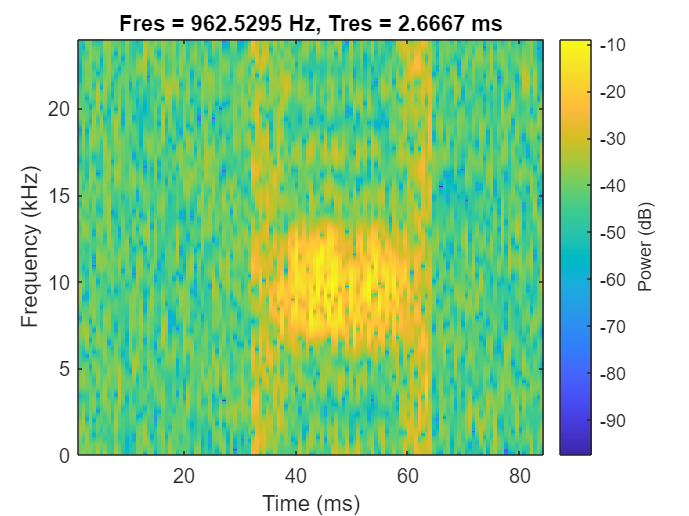

% replace the beginning and ending with noise
yy = timeShaping(yyn, 0.3);     % adjust the noise floor scaling to 0.3
pspectrum(yy,fs,"spectrogram")

% save the spectrogram as a picture file
filename = "bigCluster.png";
saveas(gcf,filename)

### Example 2 --  Generating a low-level cluster together with a strong signal in spectrogram

fs = 48000;             % this is the sampling frequency

% design a band-pass filter that is narrower than before
designedFilter = designfilt('bandpassiir', ...
    'StopbandFrequency1',0.35,'PassbandFrequency1',0.45, ...
    'PassbandFrequency2',0.55,'StopbandFrequency2',0.65, ...
    'StopbandAttenuation1',60,'PassbandRipple',1, ...
    'StopbandAttenuation2',60);

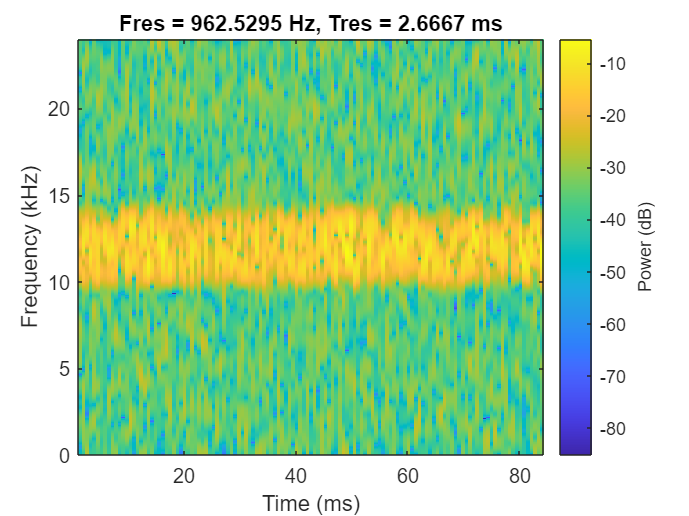

nn = 1024*4;                % the total number of samples
dat = randn(nn,1);          % generated normal distributed random values

% filter the random values to create a narrow band noise
yy = filter(designedFilter,dat);
xx = dat*0.1 + yy;
pspectrum(xx,fs,"spectrogram")

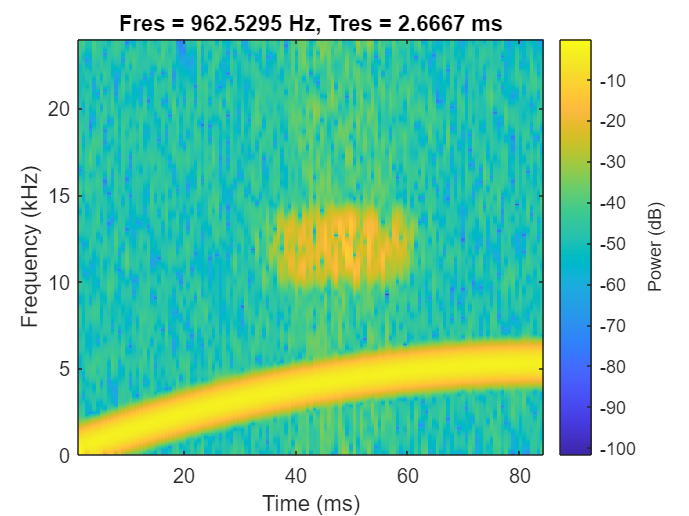

% replace the beginning and ending with noise
yy = timeShaping(xx, 0.7);  % adjust the noise floor scaling to 0.7

% generating a chirp signal 
t = (0:nn-1)/fs;
c1 = chirp(t,300,t(end),5300,'quadratic',0,'convex') + ...
    randn(size(t))/100;

% adding the chirp signal and reducing the level of the cluster
yy = yy*0.5+c1';

pspectrum(yy,fs,"spectrogram")

% save the spectrogram as a picture file
filename = "smallCluster.png";
saveas(gcf,filename)

Copyright (c) 2024, The MathWorks, Inc.